%% Simulation of linear system of monocopter with flaps 
% clc
% clear all
% close all

load gyro_x_flap.mat
load gyro_y_flap.mat
load gyro_x_flap_quat.mat
load gyro_y_flap_quat.mat
load jerk_scaling_factor_x.mat
load jerk_scaling_factor_y.mat
 
% load ka_flap.mat
% load ka_flap_NDI.mat

%% Parameters
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
Jxx = 0.014; % symmetrical so most of it is abt x so therefore Jxx
Jzz = 0.0151724197;
pitch = 41;
pitch = abs(pitch);
plot_variable = 10;
% (bod pitch * ka * servo pitch) contributes to lift force for disk torque
ka = 1; % .01,.03,.05,.07,.09,.11,.13
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -22.0440;
rps_squared = rps^2;
cl = 0.11;
cd = 0.023; 
g = 9.81;
rho = 1.225;
radius = 0.61;
chord_length = 0.1;
mass = 0.16;
altitude = 1.5;
torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
moving_axis = 'x';

if moving_axis == 'x'
    com = 1/(-(g + drag_rotation)); % omega abt y is negative (roll) linear acc x
elseif moving_axis == 'y'
    com = 1/((g + drag_rotation)); % omega abt x is positive (pitch) linear acc y
end

linesize = 3;
Fontsize = 10;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol
if moving_axis == 'x'
    %jerk_scaling_factor_x = jerk_scaling_factor_x*0.256 % impt, for x coordinates needs to scale down up 0.5
    jerk_scaling_factor_x = 0.5
    u3 = 1/3*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x
    u = sin((2.2*t)-(pi/2)); % omega abt y, linear acc x
    u3 = jerk_scaling_factor_x.*u3; % omega abt y, linear acc x
    u = jerk_scaling_factor_x.*u; % omega abt y, linear acc x

elseif moving_axis == 'y'
    %jerk_scaling_factor_y = jerk_scaling_factor_y*0.8
    jerk_scaling_factor_y = 0.95
    u3 = 1/3*sin((2.5*t)-(pi)); % omega abt x, linear acc y
    u = sin((2.5*t)-(pi)); % omega abt x, linear acc y
    u3 = jerk_scaling_factor_y.*u3; % omega abt x, linear acc y
    u = jerk_scaling_factor_y.*u; % omega abt x, linear acc y

end

jerk_scaling_factor_x = 0.5000

%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 1;
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
%stf = servo/(1+(servo*H_servo));
stf = feedback(servo,1);
% isstable(stf)
% pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot = stf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

%[omega_dot_controller,info] = pidtune(omega_dot,'PID');
omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

% to simulate step input of a single servo angle
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(stf, t, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference')
%legend('Kp = 1',  'Kp = 11',  'Kp = 21')

%% to simulate disturbance step input

[omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')

omega_dot_pi =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.0328, Ki = 1.01, Kd = 0.000267
 
Continuous-time PID controller in parallel form.
Model Properties


info_d = struct with fields:
                Stable: 1
    CrossoverFrequency: 64.4256
           PhaseMargin: 64.7364


disturbance_torque_tf = 1/(Jxx+(H_omega_dot_tf*stf*torque_w_mass)) % w feedback

disturbance_torque_tf =
 
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s + 0.0274
  ----------------------------------------------------
  1.243e-13 s^3 + 1.808e-07 s^2 + 1.071e-05 s + 1.698
 
Continuous-time transfer function.
Model Properties


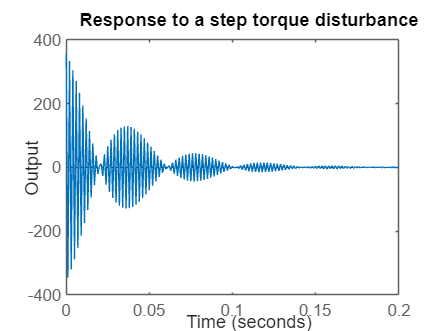

%disturbance_torque_tf = ((s^2)*com)/(((s^2)*com)+(H_omega_dot_tf*omega_dot)) % w feedback
% disturbance_torque_tf = 1/Jxx % wo feedback
dt = 0:0.001:0.2;
Config = RespConfig('Amplitude',5);
step(disturbance_torque_tf, dt, Config) % step function here is in the form of a servo angle 
ylabel('Output')
title('Response to a step torque disturbance')

% snap
snap = (s^2)*com*omega_dot*(1/(s^2))*1/com; % snap only
%[snap_controller,snap_info] = pidtune(snap,'PD'); % controller only needed for omega abt y, linear acc x
snap_tf = feedback(snap,1); % jerk and snap INDI
% isstable(snap_tf)
% pole(snap_tf)


snap = lsim(snap_tf,u3,t); % INDI cant be tested

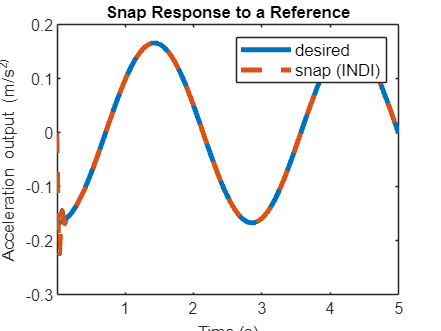

plot (t,u3,'LineWidth',linesize)
hold on
plot(t,snap,'lineStyle','--','LineWidth',linesize)
hold off
xlim([0.011 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Snap Response to a Reference','FontSize',Fontsize)
legend('desired','snap (INDI)','FontSize',Fontsize)

% snap + jerk
D = 0*plot_variable; 
omega = (s+D)*com*omega_dot_tf*(1/(s^2))*1/com; % jerk only
[omega_controller,omega_info] = pidtune(omega,'P')

omega_controller =
 
  Kp = 38.9
 
P-only controller.
Model Properties


omega_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 38.8519
           PhaseMargin: 89.9859


omega_tf_ndi = omega; % jerk and snap NDI
omega_tf = feedback(omega_controller*omega,1); % jerk and snap INDI
% isstable(omega_tf)
% pole(omega_tf)


jerk = lsim(omega_tf,u3,t);

jerk_ndi = lsim(omega_tf_ndi,u3,t);

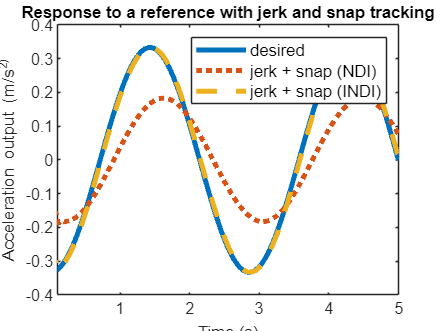

plot (t,u3*2,'LineWidth',linesize)
hold on
plot(t,jerk_ndi + snap,'lineStyle',':','LineWidth',linesize)
plot(t,jerk+snap,'lineStyle','--','LineWidth',linesize)
%plot(t,jerk+snap+gyro_y_flap,'LineWidth',linesize) % linear acc y
%plot(t,jerk+snap+gyro_x_flap,'LineWidth',linesize) % linear acc x
hold off
xlim([0.1 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a reference with jerk and snap tracking','FontSize',Fontsize)
legend('desired','jerk + snap (NDI)','jerk + snap (INDI)','FontSize',Fontsize)

% quat u3
angle = com*omega_dot_tf*(1/(s^2))*1/com;
[angle_controller,angle_info] = pidtune(angle,'PD')

angle_controller =
 
             
  Kp + Kd * s
             

  with Kp = 300, Kd = 21.2
 
Continuous-time PD controller in parallel form.
Model Properties


angle_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 24.5139
           PhaseMargin: 60.0000


angle_tf = feedback(angle_controller*angle,1);
angle_tf_ndi = angle;
% isstable(angle_tf)
% pole(angle_tf)

quat_3 = lsim(angle_tf,u3,t);

quat_ndi_3 = lsim(angle_tf_ndi,u3,t);

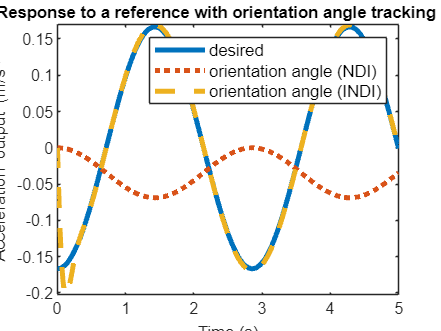

plot (t,u3,'LineWidth',linesize)
hold on
plot(t,quat_ndi_3,'lineStyle',':','LineWidth',linesize)
plot(t,quat_3,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a reference with orientation angle tracking u3','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)

% quat u1
quat = lsim(angle_tf,u,t);

quat_ndi = lsim(angle_tf_ndi,u,t);

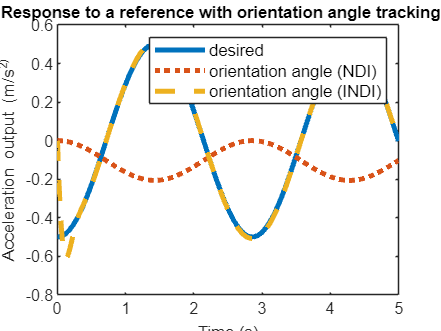

plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat_ndi,'lineStyle',':','LineWidth',linesize)
plot(t,quat,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a reference with orientation angle tracking u','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)

%% compute precession
% compute when linear acc x
if moving_axis == 'x' % negative one added to sync w the derivatives obtained from test_aux in exp_flat 
    precession_jerk_snap_gyro_y_flap = 1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_quat_3_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_quat_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_jerk_snap_gyro_y_flap = lsim(precession_jerk_snap_gyro_y_flap,jerk_scaling_factor_x.*(2/3*sin((2.5*t)-(pi))),t); % linear acc y
    precession_quat_3_gyro_y_flap = lsim(precession_quat_3_gyro_y_flap,jerk_scaling_factor_x.*(1/3*sin((2.5*t)-(pi))),t);
    precession_quat_gyro_y_flap = lsim(precession_quat_gyro_y_flap,jerk_scaling_factor_x.*(sin((2.5*t)-(pi))),t);
    
    precession_radius_y_jerk = abs(altitude*tan((jerk+snap+quat_3)*com));
    precession_radius_y_quat = abs(altitude*tan((quat)*com));

    gyro_y_flap = precession_jerk_snap_gyro_y_flap + precession_quat_3_gyro_y_flap;
    gyro_y_flap_quat = precession_quat_gyro_y_flap;

    gyro_y_flap = gyro_y_flap.*precession_radius_y_jerk;
    gyro_y_flap_quat = gyro_y_flap_quat.*precession_radius_y_quat;


    % gyro_y_flap = (((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_y
    % gyro_y_flap_quat = (((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_y

% compute when linear acc y
elseif moving_axis == 'y' % negative one added to sync w the derivatives obtained from test_aux in exp_flat, scaled it through the other axis' signal
    precession_jerk_snap_gyro_x_flap = -1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_quat_3_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_quat_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
    precession_jerk_snap_gyro_x_flap = lsim(precession_jerk_snap_gyro_x_flap,jerk_scaling_factor_y.*(2*1/3*(sin((2.2*t)-(pi/2)))),t); % linear acc y
    precession_quat_3_gyro_x_flap = lsim(precession_quat_3_gyro_x_flap,jerk_scaling_factor_y.*(1/3*(sin((2.2*t)-(pi/2)))),t);
    precession_quat_gyro_x_flap = lsim(precession_quat_gyro_x_flap,jerk_scaling_factor_y.*((sin((2.2*t)-(pi/2)))),t);
    
    precession_radius_x_jerk = abs(altitude*tan((jerk+snap+quat_3)*com));
    precession_radius_x_quat = abs(altitude*tan((quat)*com));

    gyro_x_flap = precession_jerk_snap_gyro_x_flap + precession_quat_3_gyro_x_flap;
    gyro_x_flap_quat = precession_quat_gyro_x_flap;

    gyro_x_flap = gyro_x_flap.*precession_radius_x_jerk;
    gyro_x_flap_quat = gyro_x_flap_quat.*precession_radius_x_quat;

    % plot (t, 2/3*(sin((2.2*t)-(pi/2))),'LineWidth',linesize)
    % hold on
    % plot(t, precession_jerk_snap_gyro_x_flap,'lineStyle','--','LineWidth',linesize) % linear acc x
    % hold off
    % ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    % xlabel('Time (s)','FontSize',Fontsize)
    % % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    % title('Gyro produced along linear y','FontSize',Fontsize)
    % 
    % xlim([0.5 5])
    % gyro_x_flap  = (-1*((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_x
    % gyro_x_flap_quat  = (-1*((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_x

end

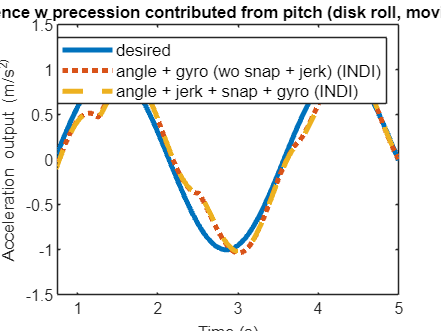

% all together w gyro, 
% for linear acc x, starting pt leads by pi/2, so contributor linear y (pitch) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol
% for linear acc y, starting pt leads by pi/2, so contributor linear x (roll) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol 
if moving_axis == 'x'
    
    special_u = sin((2.2*t)-(pi/2)); % precession contributed by linear acc y for linear acc x
    %special_u = u;
    plot (t,special_u,'LineWidth',linesize)
    hold on
    plot(t,quat+gyro_x_flap_quat,'lineStyle',':','LineWidth',linesize) % linear acc x  
    plot(t,jerk+snap+quat_3+gyro_x_flap,'lineStyle','--','LineWidth',linesize) % linear acc x
    
    hold off
    
    xlim([0.75 5]) % linear acc x
      
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    %xticklabels({'0.5','1','1.5','2','2.5','3','3.5','4','4.5','5'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Response to a reference w precession contributed from pitch (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','angle + gyro (wo snap + jerk) (INDI)','angle + jerk + snap + gyro (INDI)','FontSize',Fontsize)

elseif moving_axis == 'y' % negative one added cos in derivatives chart, gyro dot is opp sign from the acc under linear x
    special_u = sin((2.5*t)-(pi)); % precession contributed by linear acc x for linear acc y
    %special_u = u;
    plot (t,special_u,'LineWidth',linesize)
    hold on   
    plot(t,quat+gyro_y_flap_quat,'lineStyle',':','LineWidth',linesize) % linear acc y
    plot(t,jerk+snap+quat_3+gyro_y_flap,'lineStyle','--','LineWidth',linesize) % linear acc y
    hold off
    
    xlim([0.75 5]) % linear acc y
    
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    % xticklabels({'0.25','0.5','1','1.5','2','2.5','3','3.5','4'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Response to a reference w precession contributed from roll (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','angle + gyro (wo snap + jerk) (INDI)','angle + jerk + snap + gyro (INDI)','FontSize',Fontsize)
end

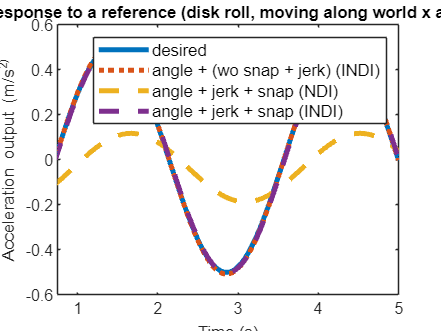

% all together
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat,'lineStyle',':','LineWidth',linesize) 
plot(t,jerk_ndi+snap+quat_ndi_3,'lineStyle','--','LineWidth',linesize)
plot(t,jerk+snap+quat_3,'lineStyle','--','LineWidth',linesize) 
hold off


if moving_axis == 'x'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Response to a reference (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','angle + (wo snap + jerk) (INDI)','angle + jerk + snap (NDI)','angle + jerk + snap (INDI)','FontSize',Fontsize)
    xlim([0.75 5]) % linear acc x

elseif moving_axis == 'y'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Response to a reference (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','angle + (wo snap + jerk) (INDI)','angle + jerk + snap (NDI)','angle + jerk + snap (INDI)','FontSize',Fontsize)    
    xlim([0.75 5]) % linear acc y

end

 %jerk_scaling_factor_x = abs(mean(transpose((jerk+snap+quat_3)./gyro_y_flap))); % linear acc x
 %jerk_scaling_factor_y = mean(transpose((jerk+snap+quat_3)./gyro_x_flap)); % linear acc y
 

%ka_flap_values = zeros(501,10);
%ka_flap_values(:,plot_variable) = jerk+snap+gyro_y_flap;


% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (INDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 

%ka_flap_values_NDI = zeros(501,10);
%ka_flap_values_NDI(:,plot_variable) = jerk_ndi+snap;

% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values_NDI(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (NDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 